Fs = 400e3 

Fs = 400000

Ts = 1/(Fs)

Ts = 2.5000e-06

res =  fft(RXn)

res = 	1.0e+03 *

  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i



num_samples = length(RXn)

num_samples = 1126450

factor = Fs/num_samples

factor = 0.3551

freq = transpose(factor*(0:num_samples-1))

freq = 	1.0e+05 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


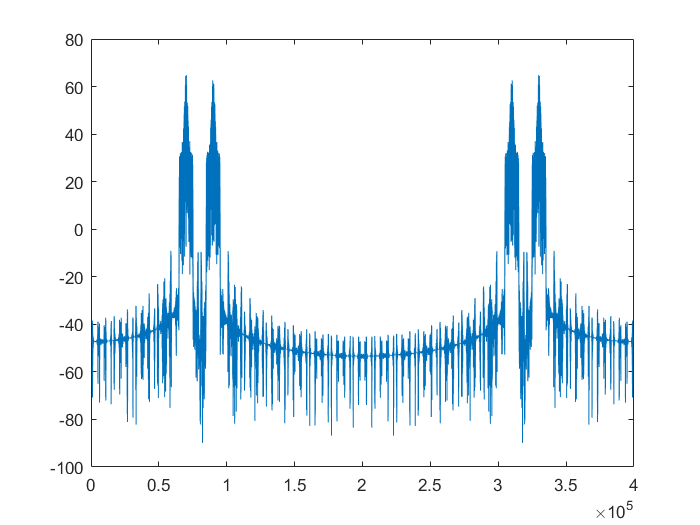



plot(freq,mag2db(abs(res)))

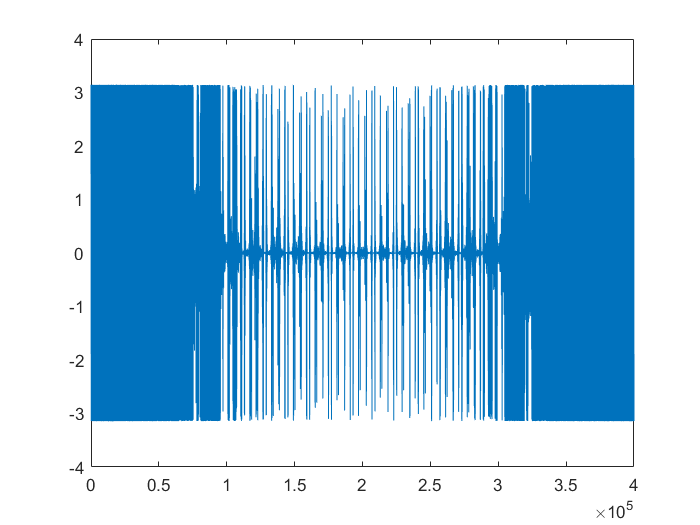

plot(freq,angle(res))


% https://stackoverflow.com/questions/28814547/matlab-low-pass-filter-using-fft
carrier_freq_index = 197129 %70kHz

carrier_freq_index = 197129

demod = circshift(res,-carrier_freq_index) + circshift(res,-(mod(-carrier_freq_index,num_samples)))

demod = 	1.0e+03 *

   2.0157 + 0.0000i
  -0.1953 - 0.6144i
  -0.0969 - 0.2289i
  -0.0360 - 0.1703i
  -0.0203 - 0.0894i
  -0.0999 - 0.1442i
  -0.0695 + 0.0658i
   0.1129 + 0.0284i
  -0.0146 - 0.0969i
   0.0269 - 0.1004i


test = ifft(demod)

test =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


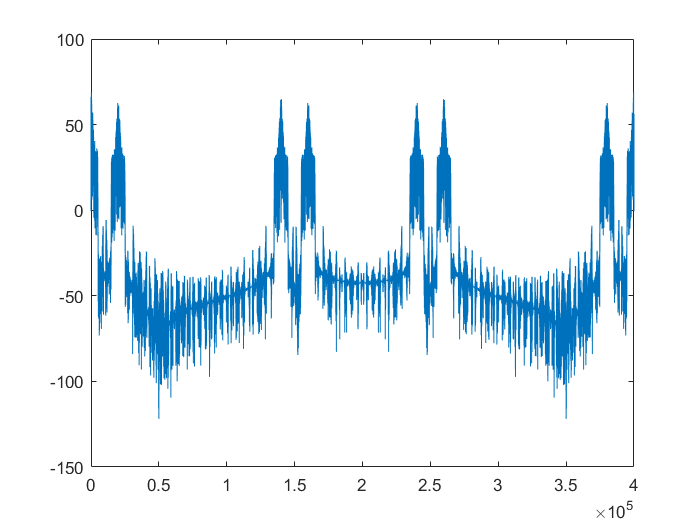

plot(freq,mag2db(abs(demod)))

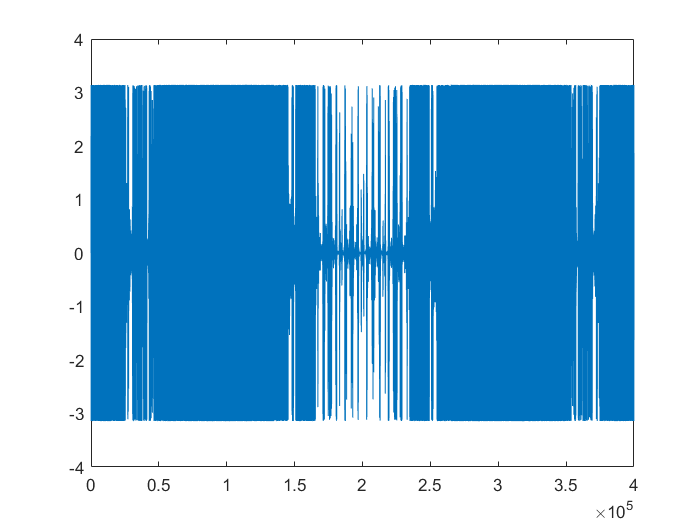

plot(freq,angle(demod))


passband_freq_index = 14081 %5kHz

passband_freq_index = 14081


rectangle = zeros(size(demod))

rectangle =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


rectangle(1:passband_freq_index+1) = 1

rectangle =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


rectangle(passband_freq_index+1:end) = 1

rectangle =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


% lowpass_filter = horzcat(ones(1,passband_freq_index),zeros(1,num_samples-passband_freq_index))
% filtered_demod = demod' .* lowpass_filter
% plot(freq,mag2db(abs(filtered_demod)))
% plot(freq,angle(filtered_demod))
mono = ifft(rectangle.*demod)

mono =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


dec_mono = downsample(mono,2)

dec_mono =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000


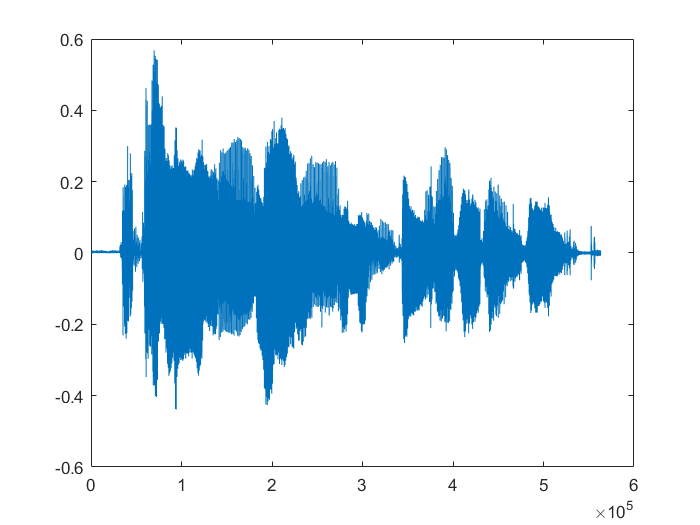

plot(dec_mono)

sound(2*dec_mono,Fs/2)